clc
clear

% %frecuencias admitidas (8000, 11025, 22050 y 44100), el tipo
% Fs = 44100;
% 
% recObj = audiorecorder(44100, 16, 1);
% 
% disp('Start speaking.')
% recordblocking(recObj, 3);
% disp('End of Recording.');
% 
% play(recObj);
% 
% y = getaudiodata(recObj);
% plot(y);
% TL = 80e-3 ;
% L = TL*Fs; 
% NFFT = 2^nextpow2(L);
% overlap= floor(0.7*L);
% figure
% pwelch(y,hamming(L),overlap, NFFT, Fs)
% [pxx,f] =pwelch(y,hamming(L),overlap, NFFT, Fs);
% 
% [pks,locs] = findpeaks(10*log10(pxx),"NPeaks",2)
% sort(f(locs))
% 
% figure
% specgram(y,NFFT,Fs,hamming(L),overlap); colorbar;
% 
% 
% %Oli ya llegie
% %hola

% switch mode
%     case 'Primera'
%         x = -5;
%     case 'Segunda'
%         x = -10;
%     case 'Tercera'
%         x = -14;
%     case 'Cuarta'
%         x = -19;
%     case 'Quinta'
%         x = -24;
%     case 'Sexta'
%         x = -29;
% end


Proyecto 1

## Afinador de instrumentos musicales

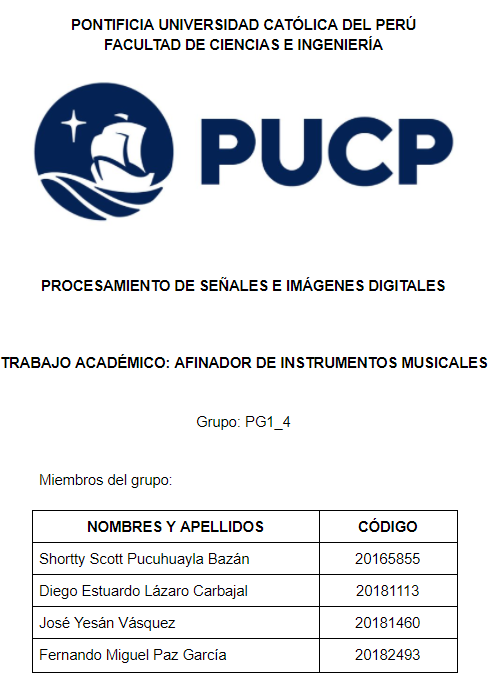

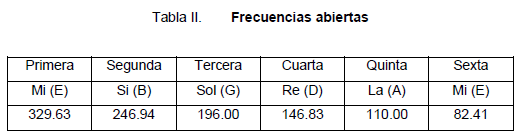

Grabaciónde la nota

fs = 2000;
recObj = audiorecorder(fs, 16, 1);
recordblocking(recObj, 2);
y = getaudiodata(recObj);


Filtraje de sonido

prompt='ingrese el número de cuerda: ';
x = input(prompt);

% F1 = 440*2^((x-1)/12);
% F2 = 440*2^((x+1)/12);
% wp1 = F1/(fs/2);
% wp2 = F2/(fs/2);
% Wp= [wp1 wp2];
% [b, a] = butter(4,Wp,'bandpass');
% y1= filter(b,a,y);

% L = 0.1*fs;
% overlap = floor(0.9*L);
% nfft = 2^nextpow2(L);
% [pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
% [pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',1);
% pk= f(locs);
% 
% pk1 = string(pk);
% app.FrecuenciaActualLabel.Text = "Frecuencia Actual: " + pk1;
% order1 = 30 + 12 * log2(pk/440);
% order2 = round(order1);
% if order2 < 46
%     n = order2 - order1;
%     if n< - 0.35 
%         app.EstadoLabel.Text = "Estado: " +  "Por encima de la frecuencia";
%     elseif n > 0.35
%         app.EstadoLabel.Text = "Estado: " +  "Por debajo de la frecuencia";
%     else
%         app.EstadoLabel.Text = "Estado: " +  "En rango";
%     end
% else
%     app.EstadoLabel.Text = "Estado: " +  "Intente de nuevo";
% end 